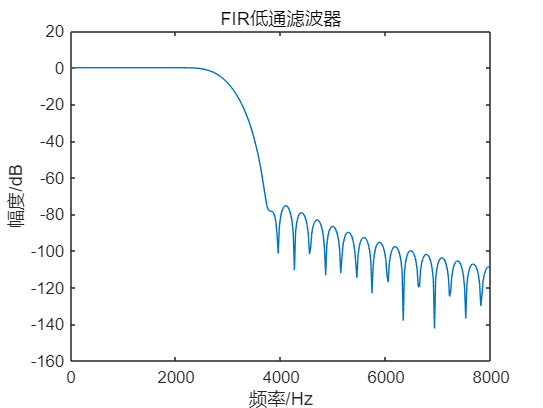

% 清除工作区和命令窗口
clc;clear;

% 读取音频文件
[y0,Fs]=audioread('dspx1.wav');
% 计算时间向量
t = (0:length(y0)-1) / Fs;
n = length(y0);

% 生成噪声信号
f=4000;                  % 噪声频率4000Hz
A=0.02;                  % 噪声幅度
Nt=(A*cos(2*pi*f*t))';  % 生成余弦噪声
y=y0+Nt;                % 将噪声加入原始信号

% 设计FIR低通滤波器参数
wp=2000*2*pi/Fs;        % 通带截止频率（弧度/采样）
ws=3800*2*pi/Fs;        % 阻带截止频率（弧度/采样）
wide=ws-wp;             % 过渡带宽度
N=ceil(12*pi/wide)+1;   % 计算滤波器阶数
wc=(wp+ws)/2;          % 计算截止频率

% 使用布莱克曼窗设计FIR滤波器
h=fir1(N, wc/pi, blackman(N+1));

% 计算并绘制滤波器的频率响应
[H, w]=freqz(h,1,1000);
w=w*Fs/(2*pi);
plot(w,20*log10(abs(H)));
xlim([0,8000]);
xlabel('频率/Hz');
ylabel('幅度/dB');
title('FIR低通滤波器');

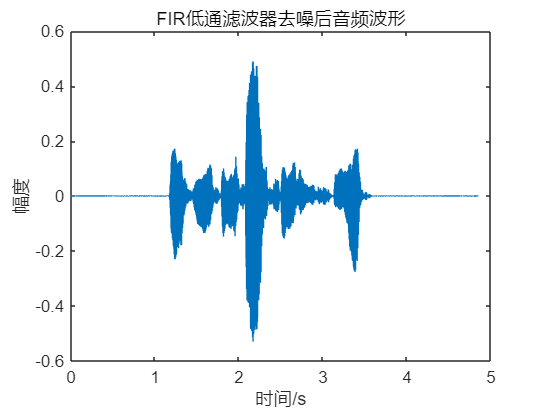


% 对含噪声信号进行滤波
y3=filter(h,1,y);

% 绘制滤波后的时域波形
figure;
plot(t,y3);
title('FIR低通滤波器去噪后音频波形');
xlabel('时间/s');
ylabel('幅度');

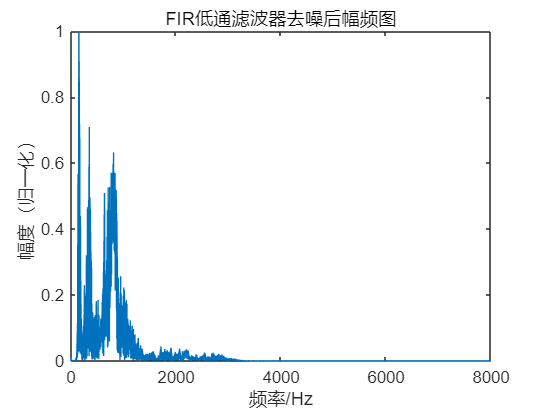


% 计算并绘制滤波后信号的频谱
figure;
Y3 = fft(y3);          % 进行傅里叶变换
M1=max(Y3);            % 获取最大值用于归一化
f = (0:n-1)*Fs/n;      % 计算频率向量
Y3 = abs(Y3)/abs(M1);  % 幅度归一化处理

% 绘制频谱图
plot(f, Y3);
title('FIR低通滤波器去噪后幅频图');
xlabel('频率/Hz');
ylabel('幅度（归一化）');
xlim([0,8000]);